# Cable-Cable Interference-Free Workspace Analysis 

clear;

### Load the robot 

Load the robot in the manner shown in `T1_load_robot.mlx`.

model_config = ModelConfig('Example spatial');
%model_options = ModelOptions(false);
cdpr_model = model_config.getModel('cross_8_cables', [], ModelModeType.COMPILED); % Compiled mode needs to fix the plotting TODO
%MotionSimulatorBase.PlotFrame(cdpr_model_cogiro, model_config_cogiro.displayRange, model_config_cogiro.viewAngle); % Plot robot

### Setup the grid

A uniform (equal spacing) grid will be setup representing the set of rays which the workspace analysis will be run.

q_min            = [0; 0; 0; pi/3; 0; pi/3];
q_max            = [1; 1; 1; pi/3; 0; pi/3];
q_step           = [0.05; 0.05; 0.05; 1; 1; 1]; 
uniform_grid     = UniformGrid(q_min, q_max, q_step, 'step_size');

### Setup plotting

dofs_to_plot_2_DoF      = [1 2]; % Plot X axis as first DoF and Y axis as second DoF

### Setup and run workspace simulator

The `RayWorkspaceSimulator` allows the ray workspace to be run. In this example, the wrench-closure workspace will be computed:

metric_cable_distance = MinCableCableDistanceMetric();

Create the simulator object using the robot model, grid and workspace condition(s):

ws_sim = PointWorkspaceSimulator(cdpr_model, uniform_grid, [], {metric_cable_distance}, []);

Run the simulator over the specified grid:

tStart = tic; 
ws_sim.run();

[WARNING] A metric with infinite limit values cannot be plotted.  To plot please set the metric limit to be finite or filter the workspace after plotting


tEnd = toc(tStart)

tEnd = 77.5825

ws_sim.compTime

ans = 75.8622

Finally, plot the resulting 2-D workspace:

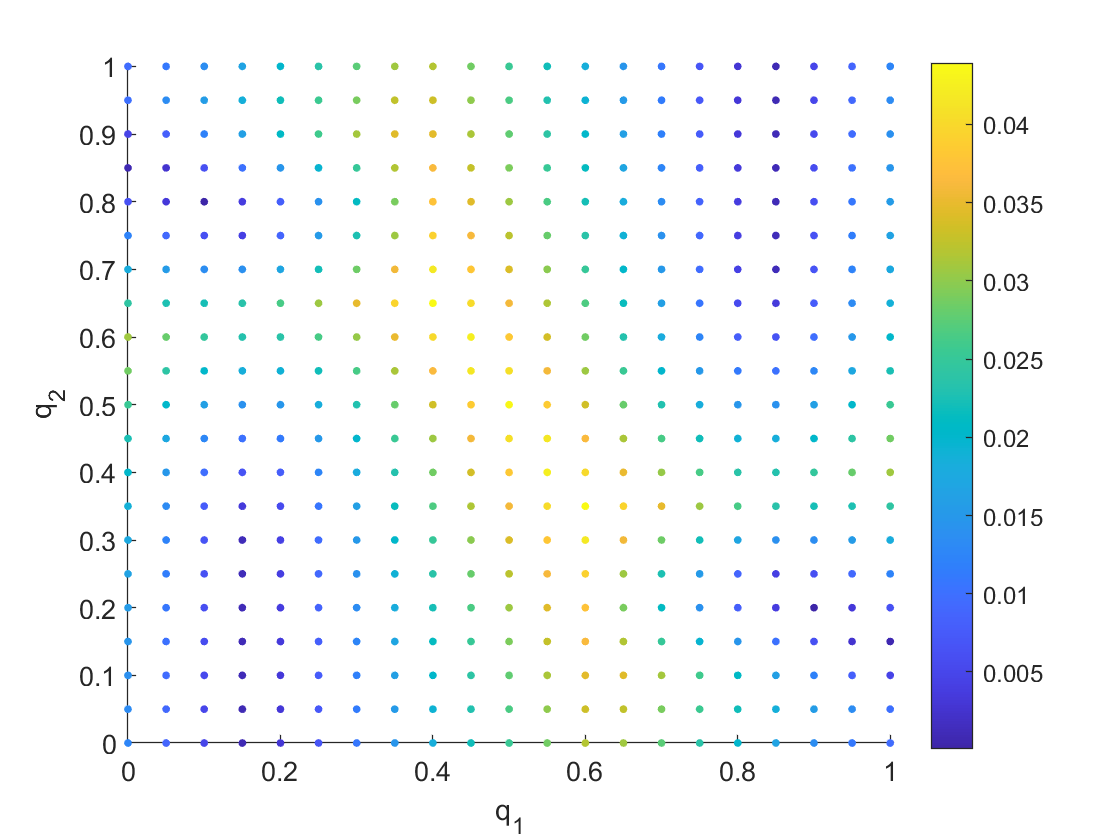

dofs_to_plot_2_DoF      = [1 2];
fixed_values = [0.5; 0.5; 0.5; pi/3; 0; pi/3];
ws_sim.workspace.plotWorkspace(dofs_to_plot_2_DoF, [0], [], fixed_values);

% axis equal;
% title('WCC Ray-Workspace Plot'); 

